60hz

clc;
clear;
B = 1;
n = 4;
wc = 2*pi*60;
aux = [wc-(B/2) wc+(B/2)]

aux =   376.4911  377.4911


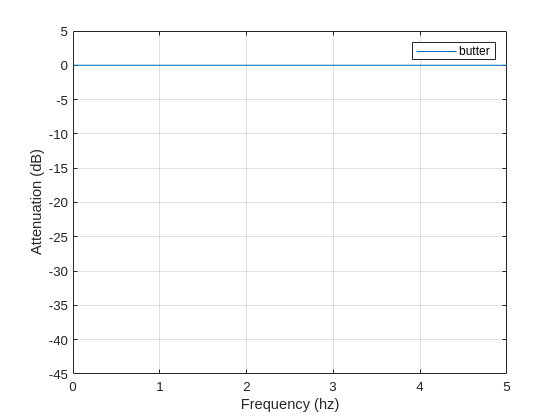

w = 2*pi*1*logspace(-2,1,4096)';

[zb,pb,kb] = butter(n,aux,'stop', "s");
[bb,ab] = zp2tf(zb,pb,kb);
[hb,wb] = freqs(bb,ab,w);
gdb = -diff(unwrap(angle(hb)))./diff(wb);

fGHz = wb/(2*pi);
plot(fGHz,mag2db(abs([hb])))
axis([0 5 -45 5])
grid on
xlabel("Frequency (hz)")
ylabel("Attenuation (dB)")
legend(["butter"])

60Hz n analogico

% Parâmetros do sinal
fs = 360;           % Frequência de amostragem (Hz)
f_notch = 60;       % Frequência da interferência (Hz)
bw = 1;             % Largura de banda da faixa rejeitada (Hz)

% Frequências normalizadas (entre 0 e 1, sendo 1 = fs/2)
Wn = [(f_notch - bw/2)/(fs/2), (f_notch + bw/2)/(fs/2)];

% Ordem do filtro
n = 4;  % quanto maior, mais acentuado o corte

% Projeto do filtro Butterworth rejeita-faixa (notch)
[b, a] = butter(n, Wn, 'stop');

% Visualização da resposta em frequência
fvtool(b, a)